## Calculate TSA per pixel

Load 3d array of NDVI and vector of dates

Contains: 

** arr_ndvi_jdasa**: 3d matrix of NDVI/MODIS data. Low-quality data is removed and gaps are filled using JDASA method (described in the article).

**arr_date**: vector of date of images MODIS/NDVI

**study_area**: binary matrix of the study area. 0 indicates a pixel outside study area and 1 a pixel inside. 


load ("arr_tsa_3d.mat");

% The matrix was split to upload it to GitHub
load("arr_ndvi_jdasa01.mat");
load("arr_ndvi_jdasa02.mat");

arr_ndvi_jdasa = cat(3,arr_ndvi_jdasa01,arr_ndvi_jdasa02);


## Others variables

%% umbral theta of sensibility 
%% recomended: 0.3, 1.53, 2.40, 3.00, 3.55 acording dNBR
theta = 2.4;

%% year of analysis. Interval (2000-2025)
year = 2022 ;

%% matix size: 722x260
%% pixel analyzed 

%%% pixel 1: affected by forest fire
% pixel described in figure 3 of article
xpixel = 167; 
ypixel = 318; 

%%% pixel 2: another pixel affected by forest fire
% xpixel = 186;
% ypixel = 295; 

%%% pixel 3: Not affected by forest fire
% xpixel = 178; 
% ypixel = 350; 

if study_area(ypixel,xpixel)==0
    disp("Warning: Pixel isn't in the study area");
end

no_records = length(arr_date);

%% Get NDVI time serie acording pixel selected
tmp = arr_ndvi_jdasa(ypixel,xpixel,:);
tmp= reshape(tmp,[],1);
tmp = double(tmp);
ndvi_timeserie = tmp*0.0001;

%% Get Avg and Std per julian day
%%  23 records per year

avg_ndvi = zeros(23,1);
std_ndvi = zeros(23,1);

for i=1:23
    jd = i:23:no_records;
    avg_ndvi(i) = mean(ndvi_timeserie(jd));
    std_ndvi(i) = std(ndvi_timeserie(jd));
end


%%% Ger anomalies
arr_anomalies =zeros(no_records,1);

diasj = 1:16:365;
for d = diasj
    tmp = find(  arr_date(:,1) == d );
    serie_s = ndvi_timeserie(tmp);
    anomalies = TSA(serie_s,theta);
    arr_anomalies(tmp) = anomalies;
end
      

## Plot a year 

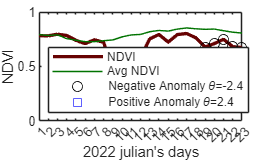

% plot only the year selected
idate = find(arr_date(:,5)==year);
ndvi = ndvi_timeserie(idate);

% mark positive and negative anomalies
an = arr_anomalies(idate);
ndvin = ndvi;
ndvin(an>=0)=nan;
ndvip = ndvi;
ndvip(an<=0)=nan;

figure;
colororder(["#670202","#007300","#7E2F8E"])

plot(ndvi,LineWidth=2);
hold on
plot(avg_ndvi);
plot(ndvin,"Ok");
plot(ndvip,"Sb");
ylim([0 1]);
ylabel("NDVI");
xlim([1 23]);
xticks(1:23);
%xticklabels(xtl);
xtickangle(45);
xlabel(year + " julian's days");

legend("NDVI","Avg NDVI","Negative Anomaly \theta=-"+theta,"Positive Anomaly \theta="+theta,Location="southwest");

## Calculate TSA with some thetas

Calculate intervals of anomalies acording NBR using some values of theta.

thetas = [0.3 1.53 2.40 3.00 3.55];
%%% Ger anoms
arr_anomalies =zeros(no_records,5);

diasj = 1:16:365;
for i=1:5
    t = thetas(i);
    for d = diasj
        tmp = find(  arr_date(:,1) == d );
        serie_s = ndvi_timeserie(tmp);
        anomalias = TSA(serie_s,t);
        arr_anomalies(tmp,i) = anomalias;
    end
end
      


## plot complete

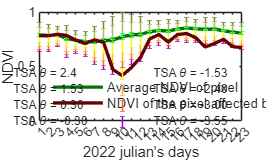

%% plot the year selected and the umbrals of theta values using color maps. 

color_tsa=[
     0.47 0.53 0.20  % Verde olivo
     0.65 0.75 0.31  % Verde claro
     0.05 0.90 0.27  % Verde
     0.97 0.98 0.06  % Amarillo
     0.97 0.70 0.25  % Naranja
     0.97 0.40 0.10  % Rojo
     0.65 0.00 0.83  % Violeta
    ];

color_tsa_bis=[
     0.47 0.53 0.20  % Verde olivo
     0.47 0.53 0.20  % Verde olivo
     0.47 0.53 0.20  % Verde olivo
     0.65 0.75 0.31  % Verde claro
     0.05 0.90 0.27  % Verde
     0.97 0.98 0.06  % Amarillo
     0.97 0.70 0.25  % Naranja
     0.97 0.40 0.10  % Rojo
     0.65 0.00 0.83  % Violeta
    ];


figure;
colororder(["#007300","#670202","#7E2F8E"])
plot(avg_ndvi,LineWidth=2);

for i=3:-1:1
hold on
    std_th_n = zeros(23,1);
    std_th_p = std_ndvi.*thetas(i);

    er(i)=errorbar(1:23,avg_ndvi,std_th_n,std_th_p);
    er(i).Color = color_tsa(4-i,:);
    er(i).LineStyle = 'none';
    er(i).CapSize=3;
    er(i).Bar.LineStyle = 'dotted';
    er(i).Bar.LineWidth = 1.5;
    hold off
end

for i=5:-1:1
hold on
    std_th_n = std_ndvi.*thetas(i).*-1; 
    if i~=1
        std_th_p = zeros(length(std_th_n),1);
    else
        std_th_p=std_ndvi.*thetas(i);
    end
    er2(i)=errorbar(1:23,avg_ndvi,std_th_n,std_th_p);
    er2(i).Color = color_tsa(i+2,:);
    er2(i).LineStyle = 'none';
    er2(i).CapSize=3;
    er2(i).Bar.LineStyle = 'dotted';
    er2(i).Bar.LineWidth = 1.5;
    hold off
end


hold on 
plot(ndvi,LineWidth=2,Color="#670202");
hold off

ylim([0 1]);
ylabel("NDVI");
xlim([1 23]);
xticks(1:23);
%xticklabels(xtl);
xtickangle(45);
xlabel(year + " julian's days");

legend({'Average NDVI of pixel', ...
    '','','','','','','','',...
    'NDVI of the pixel affected by forest fire'},FontSize=8,Location="southwest",NumColumns=1);
legend("boxoff");


ah1 = axes('Position',get(gca,'position'),'Visible','off');
er = flip(er);
er3= [er er2];
leg = legend(ah1, er3,{
    'TSA \theta = 2.4', ...
    'TSA \theta = 1.53', ...
    'TSA \theta = 0.30', ...
    'TSA \theta = -0.30', ...
    'TSA \theta = -1.53', ...
    'TSA \theta = -2.40', ...
    'TSA \theta = -3.00', ...
    'TSA \theta = -3.55'},FontSize=7,Location="southeast",NumColumns=2);
legend("boxoff");

## This commented code make a arr_tsa 3d-matrix

**!!! The code takes arround 30 minutes in a Intel i7 9th gen laptop**

**arr_tsa **is using in a tsa_map_per_day.m code to generate maps

and is in arr_tsa_3d.mat file.

% % % thetas = [0.3 1.53 2.40 3.00 3.55];
% % % arr_tsa =zeros(722,260,598);
% % % jdays = 1:16:365;
% % % 
% % % bp=waitbar(0,'Processing TSA'); 
% % % for d = jdays
% % %     for i=1:722
% % %         for j=1:260
% % %             if ~isnan(study_area(i,j))
% % %                 tmp = find(  arr_date(:,1) == d );
% % %                 serie_s = reshape( arr_ndvi_jdasa(i,j,tmp),[],1);
% % %                 dserie_s = double(serie_s) * 0.0001;
% % %                 anomalias = TSA(dserie_s,thetas);
% % %                 arr_tsa(i,j,tmp) = anomalias;
% % %             end
% % %         end
% % %     end
% % %     waitbar(d/365,bp,sprintf('Processing TSA (%3.2f%%) ',(d/365*100)));
% % % end
% % % close (bp);


function anomalies = TSA(serie,umbral)
% This function scans a time series and returns a vector of anomalies
% detected in the time series. The function takes two arguments:
% 1. serie: a vector of numerical values representing the time series
% 2. umbral: a numerical value representing the threshold for anomaly   
% detection
% The function returns a vector of the same length as the input series,
% with 1 indicating an anomaly and 0 indicating a normal value.
% The function uses the f_anomaly function to detect anomalies in the   
% time series.
% Usage:
% anomalies = f_anomaly_scan(serie, umbral)
% Example:
% serie = [1, 2, 3, 4, 5, 100, 7, 8, 9]
% umbral = 10           
% anomalies = f_anomaly_scan(serie, umbral)             
% The output will be a vector of the same length as serie, with 1 at the
% index of the anomaly (100) and 0 at all other indices.
    

if(nargin<2||nargin>3)
    error("Número de parametros incorrectos");
else
   anomalies = zeros(length(serie),1);
    for i=1:length(serie)
        [anomalies(i)] = TSA_m(serie(i),serie,umbral);
    end
end

end


function [anomaly,value] = TSA_m(test,serie,umbral)
% This function detects anomalies in a time series using the Z-score method.
% It takes three arguments:
% 1. test: a numerical value representing the test value
% 2. serie: a vector of numerical values representing the time series
% 3. umbral: a numerical value representing the threshold for anomaly detection
% The function returns two values:
% 1. anomaly: a numerical value indicating the type of anomaly detected
%    1 for positive anomaly, -1 for negative anomaly, and 0 for no anomaly
% 2. value: the difference between the test value and the mean of the series
% Usage:
% [anomaly,value] = f_anomaly(test, serie, umbral)
% Example:
% test = 100
% serie = [1, 2, 3, 4, 5, 6, 7, 8, 9]
% umbral = 2.5
% [anomaly,value] = f_anomaly(test, serie, umbral)
% The output will be:
% anomaly = 1 (positive anomaly)
% value = 94 (the difference between test and the mean of the series)

if(nargin<2||nargin>3)
    error("Número de parametros incorrectos");
else
    if(nargin==2)
        umbral= [2.0 2.25 2.5 2.75 3.0];
    end
    if( isnumeric(test ) && isnumeric(serie))
        mean_s = mean(serie,"all","omitnan");
        std_s = std(serie,0,"all","omitnan");

        if(length(test)>1)
            mean_t = mean(test,"all","omitnan");
        else
            mean_t = test;
        end
    else
        error("Los parametros deben ser numericos");
    end
end

if( mean_t > (mean_s + (umbral*std_s)))
    anomaly = 1;
elseif(mean_t < (mean_s - (umbral*std_s)))
    anomaly=-1;
else
    anomaly=0;
end

value = mean_t - mean_s;
end

